% sat4_main.m
clear; clc; close all;

%% ---------- 0) параметры реакционных колес ----------
reaction_wheel_params4;     % создаёт: B, Bplus, tau_max, Jr, IrR_local, …

%%% ---------- 1) параметры КА (корпус + 4 колеса) ----------
ms = 2.6;                    % масса КА, кг
lx = 0.10; ly = 0.10; lz = 0.20;   % габариты, м

Is = (ms/12) * diag([ly^2+lz^2, lx^2+lz^2, lx^2+ly^2]);  % корпус
I  = Is + 4*IrR_local;        % + 4 одинаковых колеса, грубо
invI = inv(I);


%% ---------- 2) начальное состояние ----------
omega0     = deg2rad([ 1;  2; -1]);   % рад/с
q0         = [1; 0; 0; 0];            % без поворота
omega_rw0  = zeros(4,1);              % скорости колес
x0 = [omega0; q0; omega_rw0];         % 3+4+4 = 11×1


%% ---------- 3) регулятор и целевая ориентация ----------
Kp = diag([0.06 0.06 0.03]);
Kd = diag([1    1    1   ]);
M_dist = [0; 0; 0];                   % возмущающий момент, Н·м
q_des  = [cosd(15/2); 0; 0; sind(15/2)];

%% ---------- 4) структура с параметрами (избегаем globals) ----------
pars.I       = I;
pars.invI    = invI;
pars.Kp      = Kp;
pars.Kd      = Kd;
pars.q_des   = q_des;
pars.B       = B;                     % 3×4
pars.Bplus   = Bplus;                 % 4×3
pars.tau_max = tau_max;
pars.Jr      = Jr;                    % скаляр
pars.M_dist  = M_dist;

%% ---------- 5) быстрая проверка псевдообратной ----------
Ttest = [1e-3; 0; -1e-3];
tau    = pars.Bplus * Ttest;
fprintf('||B*tau - T|| = %.2e\n', norm(pars.B*tau - Ttest));

||B*tau - T|| = 3.07e-19


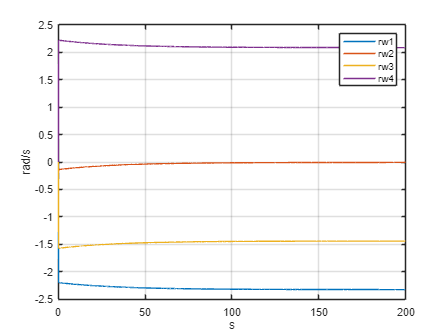

% ОК, если ≤ 1e-9

%% ---------- 6) интегрирование ODE ----------
tspan = [0 200];
opts  = odeset('MaxStep', 0.05);

[t, x] = ode45(@(t,x) rhs_attitude4(t, x, pars), tspan, x0, opts);

%% 6) plots
omega_rw = x(:,8:11);
figure; plot(t,omega_rw);
legend('rw1','rw2','rw3','rw4'); xlabel('s'); ylabel('rad/s'); grid on;

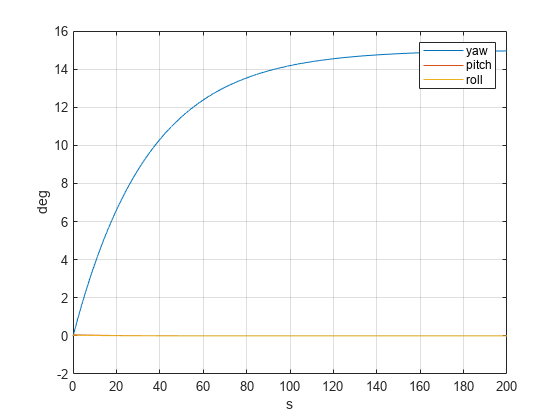


q = x(:,4:7);
q = q./vecnorm(q,2,2);
euler = zeros(length(t),3);
for i=1:length(t)
  R = quat2rotm(q(i,:));
  euler(i,:) = rad2deg(rotm2eul(R,'ZYX'));
end
figure; plot(t,euler);
legend('yaw','pitch','roll'); xlabel('s'); ylabel('deg'); grid on;